# Dynamic Structural Econometrics - Estimating Dynamic Auctions

Prepared by [Aaron Barkley, University of Melbourne](https://sites.google.com/site/aaronmbarkley)

## Introduction

This file covers the estimation of dynamic auctions, with a focus on ascending auctions. We will cover two cases:

- No bidding frictions: English auctions are equivalent to (dynamic) button or (static) second-price sealed bid auctions.

- Frictions prevent prevent perfect attention to the auction. This rationalizes "jump bidding," but requires a different estimation approach.

## 1. Ascending auctions without frictions

#### Strategic equivalence to second-price sealed bid auctions

The English auction (or open-cry ascending auction) is a common practical implementation of an ascending auction. In an English auction, bidders call out bids, or are prompted by the auctioneer to bid at certain levels, until not further bids are placed. The good is then sold at the highest bid. 

If bidders can continuously and perfectly monitor the auction and place bids at very fine intervals, this auction format is well-approximated by the Japanese or button auction: the exogenously increases over time, and bidders exit the auction when the price exceeds their chosen maximum bid. This gives rise to a dominant strategy: bidders should only drop out at the moment the price exceeds their valuation. This generates a strategic equivalence to the second-price sealed bid auction, in that observed bids (or drop-out points) directly reveal bidders' private values. Then, knowledge of bids placed in the auction allows the econometrician to estimate private value distributions under the iid private values assumption. It is common to do this non-parametrically, which we briefly review below.

#### Review of non-parametric estimation

One of the advantages of this model is that it allows for very flexible estimation of demand, which in this setting is equivalent to the distribution of valuations. Because we can express a point-estimate of valuations in terms of distributions, we can specify these distributions fully non-parametrically. We need to estimate both the distribution function and the density function. Estimating the distribution function non-parametrically is easy. Suppose we have a sample $x_1,...,x_n$of $n$ points that are i.i.d. draws from a distribution $F$. The empirical cdf $\hat{F}$ for the distribution function is given by


$$\hat{F}(x) = \frac{1}{N} \sum_{n=1}^N 1\{x_{n} \leq x\}$$


so that $\hat{F}(x)$ is simply the fraction of the sample that is less than $x$.

Estimating the density requires a little more care. Among the most popular methods for implementing density estimation is kernel density estimation, which uses a kernel function to smooth over the data points present in the sample. Suppose we want to estimate the density function $f$ at a particular point $x$. The standard kernel density estimator for a sample of $n$ i.i.d. draws $x_1,...,x_n$ is given by


$$\hat{f}(x) = \frac{1}{nh} \sum_{i=1}^n K\left(\frac{x - x_i}{h} \right)$$


where $K(\cdot)$ is a kernel function that weights different observations $x_i$ by their distance to $x$ and $h$ is the bandwidth, a smoothing parameter that determines how much points "far away" from $x$ should be valued. Often, a normal kernel is used, meaning that $K(\cdot)$is the standard normal density function so that the kernel weight for observation $x_i$ is given by

$K\left(\frac{x - x_i}{h}\right) = \frac{1}{\sqrt{2\pi}} \exp\left(\frac{-(x- x_i)^2}{2h^2}\right)$.

When the bandwidth parameter $h$ is very small, then only points that are very close to $x$ will receive a significant weight. To see this, note that if $h$ is very small and $x - x_i >0$, then the argument into the normal density will be very large. The standard normal density evaluation at a point far away from zero is very small, so the resulting kernel weight for $x_i$ will be very small. However, if $x - x_i \approx 0$, then the kernel weight will be much higher as the low bandwidth parameter won't be enough to push the argument far away from zero. The result of this is that a low value for the bandwidth parameter is prone to *over-fitting *that generates a very jumpy estimate for the density that will match the particular idiosyncrasies of the sample too closely*.* Conversely, a very large value for $h$ will generate *over-smoothing* that provides too much weight to extremal points, flattening regions that should have high density and putting too much weight into the tails of the distribution. To see this effect, consider the following example of 250 random draws from a standard normal distribution.

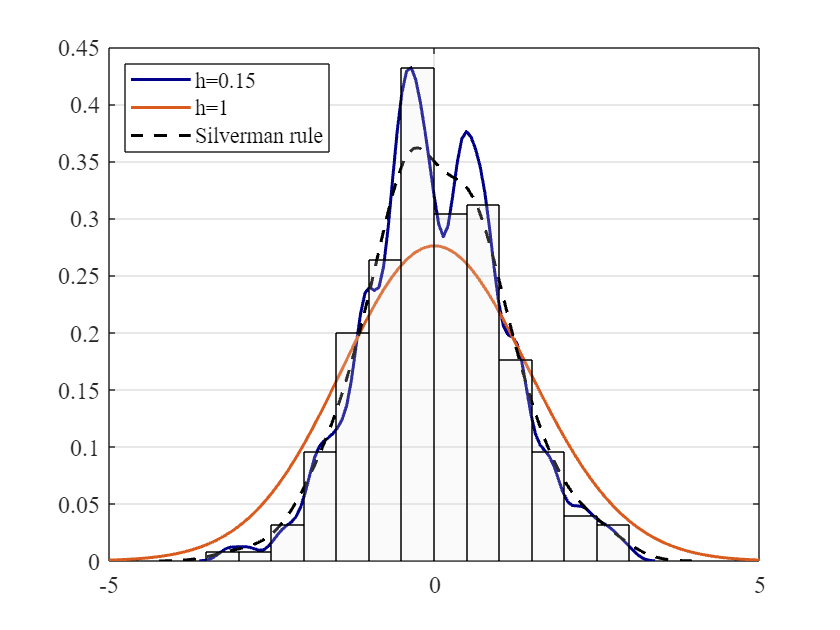

rng(2025); % Set seed for reproducibility
test_draws = randn([250,1]);
ksdensity(test_draws,'Bandwidth',0.15);
hold on
ksdensity(test_draws,'Bandwidth',1);
[f,x]=ksdensity(test_draws);
plot(x,f,'--k');
h=histogram(test_draws,'Normalization','pdf');h.FaceColor=[0.9,0.9,0.9];h.FaceAlpha=0.2;
xlim([-5,5]);
hold off;
legend('h=0.15','h=1','Silverman rule','location','northwest')

## Estimation when only the winning bid is observed

In practice, it is extremely common to observe only the winning bid and the total number of bidders when working with auction data. Because of this, it is necessary for our estimation strategy to handle these cases as well. When dealing with the IPV case, we can use the result that when random variables are i.i.d. draws from a distribution with cdf $F$, then there is a monotonic mapping from the distribution function of any order statistic $(i:n)$, or the $i$-th highest draw from a set of $n$ draws


$$F^{(i:n)}(s) = \frac{n!}{(n-i)!(i-1)!} \int_0^{(F(s)} t^{i-1}(1-t)^{n-i} dt$$


This equation means that observing any order statistic from the auction results is sufficient to identify the distribution of valuations: we can observe the lowest bid in each auction, the third highest bid in each auction, or any other order statistic, and the identification of the distribution will not be affected.

mu_b = 7.5; % Average bidder's home valuation, in $100,000's.
sigma_b = 0.75; % Standard deviation of bidder valuation distribution.
BuyerValueDist = makedist('Normal','mu',mu_b,'sigma',sigma_b); % Assume a normal distribution for valuations

num_auc = 1000; % Simulate 1000 auctions
N=5; % Assume five bidders at each auction
rng(2022); % Fix the random number generator seed so we can reproduce everything exactly.

% Draw valuations from the distribution defined above:
value_draws = random(BuyerValueDist,[num_auc,N]);

### Second-price

In second-price auctions in which only the transaction price is observed, the econometrican observes the second highest bid, or $b^{(n-1:n)}$.


$$F_{V}^{(N-1:N)}(w) =N(N-1) \int_0^{ F_V(w)} t^{N-2} (1-t) dt$$


In practice, it is simpler to work with the following, equivalent expression in computation:


$$F_{V}^{(N-1:N
)}(w) = \sum_{j=N-1}^N {N \choose j} F_V(w)^j\big[1-F_V(w)\big]^{N-j} = N F_V(w)^{N-1} \big[1-F_V(w)\big] + F_V(w)^N \\ \Rightarrow \quad F_V^{(N-1:N)}(w) = NF_V^{N-1}(w) - (N-1)F_V^N(w)$$


This gives us the equations we need to transform the observed transaction prices into estimates of the cdf $F_V$.

In fact, we can exploit the polynomial structure of the equation to use polynomial root finding algorithms instead of general non-linear equation solvers. Our estimate for $F_V(w)$ is the (unique) root in (0,1) of $\lambda_w(Z)$ defined by


$$(N-1)Z^N- NZ^{N-1}+ F_V^{(N-1:N)}(w) = 0$$


For example, if $N=2$, then $\hat{F}_V(w) = 1 - \sqrt{1-F_V^{(N-1:N)}(w)}$.

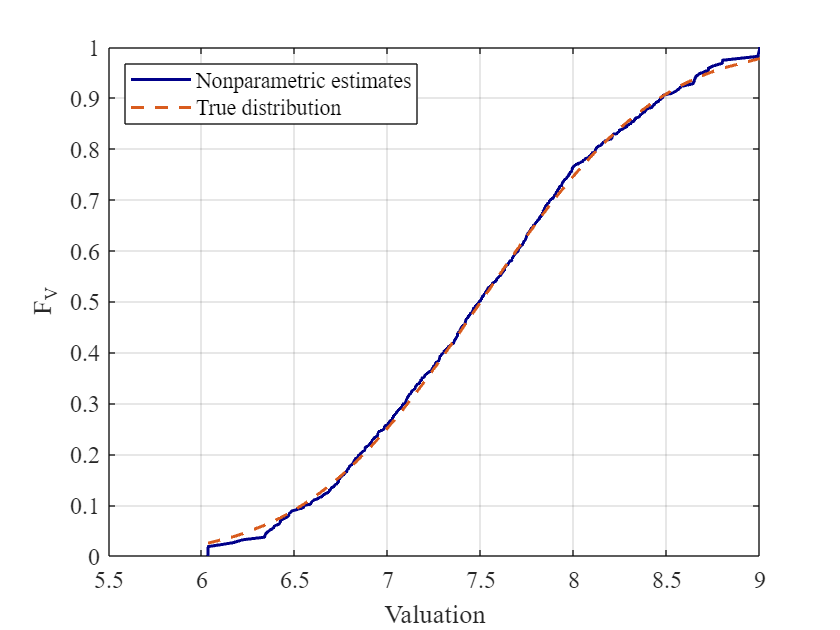

WBids_second=sort(value_draws,2,'descend');
WBids_second=WBids_second(:,2);

[F_V2,X_V2]=ecdf(WBids_second);
F_V=zeros(size(F_V2));

for j=1:length(X_V2)
    gap = zeros(1,N-2);
    poly_vec = [(N-1), -N, gap, F_V2(j)];
    try
        F_set = roots(poly_vec); % Find all roots of the polynomial lambda(Z)
        F_V(j) = F_set(F_set >= 0 & F_set<=1); % Pick the (unique) real root in (0,1)
    catch
        if j==1
            F_V(j)=0;
        else
            F_V(j) = F_V(j-1);
        end
    end
end


plot(X_V2,F_V,'-',X_V2,normcdf(X_V2,mu_b,sigma_b),'--');
xlim([5.5,9]);
xlabel('Valuation');
ylabel('F_V');
legend('Nonparametric estimates','True distribution','location','northwest');

We can also estimate the distribution parametrically. This involves using the likelihood of observing each transaction price $w$ as a function of the overall valuation distribution    


$$f_{V}^{(N-1:N)}(w) = N(N-1) F_V(w)^{N-2} \big[1-F_V(w)\big]f_v(w)$$


This equation states that there are $N(N-1)$ different ways for $N-2$ bidders to have a valuation strictly less than the winning bid (i.e., $F_V(w)^{N-2}$), while one bidder has a valuation exactly equal to the winning bid (i.e., $f_v(w)$), and the winning bidder's valuation exceeds the highest bid/second highest valuation $1-F_V(w)$.

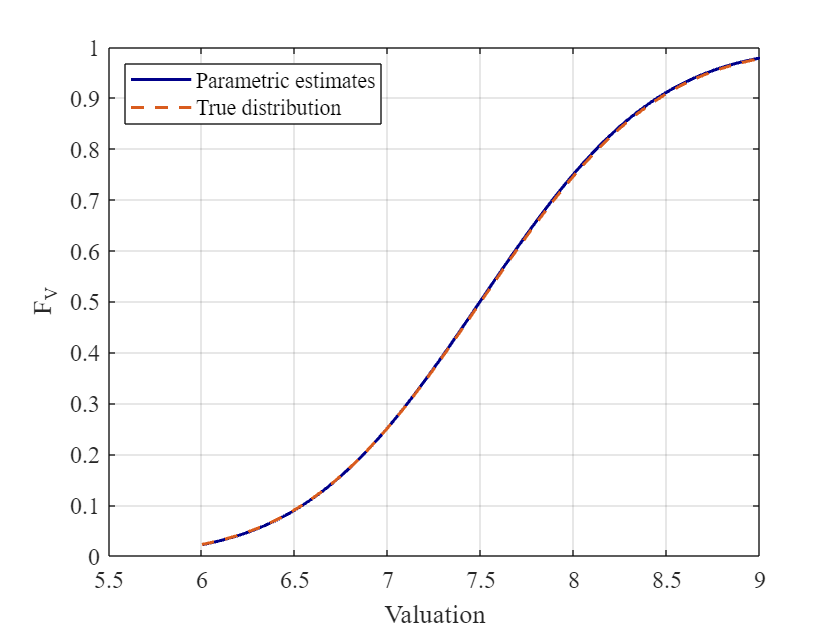


second_price_like = @(theta) -sum(log(N*(N-1)*normcdf(WBids_second,theta(1),theta(2)).^(N-2).*(1-normcdf(WBids_second,theta(1),theta(2))).*normpdf(WBids_second,theta(1),theta(2))));
[theta_hat_second,~]=fminunc(second_price_like,[5,1],optimoptions('fminunc','Display','none'));

v=linspace(6,9,100);
plot(v,normcdf(v,theta_hat_second(1),theta_hat_second(2)),'-',v,normcdf(v,mu_b,sigma_b),'--');
xlim([5.5,9]);
xlabel('Valuation');
ylabel('F_V');
legend('Parametric estimates','True distribution','location','northwest');

## 2. Ascending auctions with bidding frictions

Now we consider auctions in which bidder face frictions and cannot continuously monitor the auction. This gives rise to jump bidding and leaving money on the table, i.e., winning bidders potentially bidding higher than the second-highest valuation. Our estimation follows Barkley, Groeger, and Miller (2021 *Journal of Econometrics*).

This section will guide you through the main estimation steps of the dynamic auction model of "Bidding Frictions in Ascending Auctions" to give an idea of the techniques involved in each step. 

To begin, recall that the auction model used has the following features:

- Valuations for each bidder $i$ at auction $j$ are given by $v_{\left\lbrace \textrm{ij}\right\rbrace } =y_j {\;x}_i +\underline{r}$ $\forall \ i \in \mathcal{I}$, where $y$ is the auction-specific component common to all bidders, $x_i$ is bidder $i$'s private valuation component, and $\underline{r}$ is the auction reserve price.

- Bids can be placed at any moment over a time interval $[0, \mathcal{T}]$, where $\mathcal{T}$ is the end time of the auction.

- Bidding opportunities are random and generated according to the following process: when a bid by bidder $i$ is currently winning (in-the-money or INM), no new bidding opportunties for bidder $i$ will arise. If bidder $i$'s bid is supplanted by another bid so that it is no longer a provisionally winning bid (out-of-the-money or OUTM), a random process will determine when the next bidding opportunity is for that bidder. Specifically, if bidder $i$'s bid is pushed OUTM at time $t$, then the next time $\tau$ for that bidder to bid is a random variable that has cdf $G_{\tau}(t)$. Note that this distribution depends on the time pushed OUTM $t$; this means that the frequency of bidding opportunities may change over the auction's duration.

- Bidders always place a bid whenever they have an opportunity to do so, provided that the minimum bid required to be INM does not exceed their valuation.

- The lowest provisionally winning bid at any moment in the auction is referred to as the ONM rate.

With these pieces in place, we can describe the estimation of the model in three steps:

- Estimate the arrival times of new bidding opportunities conditional on being pushed OUTM at time $t$. Because we observe when all bids were placed, this is directly identified from the data and can be done with readily available methods.

- Use the distribution of bids to estimate the (joint) distribution of (pairs of) valuations within an auction.This is the "hard part" as it requires construction of a likelihood function over pairs of bids as a function of the joint distribution of valuation pairs. This gives the distribution of $(V_1, V_2)$, or the joint distribution of a pair of valuations within an auction

- Use deconvolution to separate  the distributions of $X$ and $Y$. This uses known methods but involves some messy numerical integration.

### a. Estimating the distribution of bidding arrival times

There are two main data files: response_times_data contains a random subset of bid times, and pre_est_data has more complete bidding data. For now we can load only the response times:

clear;
load Data/response_times_data.mat

 Each column corresponds to a single bid, where each row has a value for "response_time", or the time that a new bid was placed, and "cross_time", which is the time that the bidder's previous bid was pushed OUTM. 

responses(1:10,:)

ans = 10×2 table
    response_time    cross_times
    _____________    ___________

        1729            1653    
        1086            1062    
        1776            1763    
        1214            1196    
        1418            1394    
        1788            1788    
        1627            1609    
        1762            1751    
        1771            1757    
         590             546    


The first entry corresponds to a bidder that submitted a bid at 1729 seconds into the auction (at about minute 29) after being pushed OUTM at 1653 seconds (27.5 minutes). 

We are primarily interested in the time elapsed between bids, which is "reponse_time" minus "cross_time". If we just want the raw, unconditional cdf we can use built-in Matlab commands

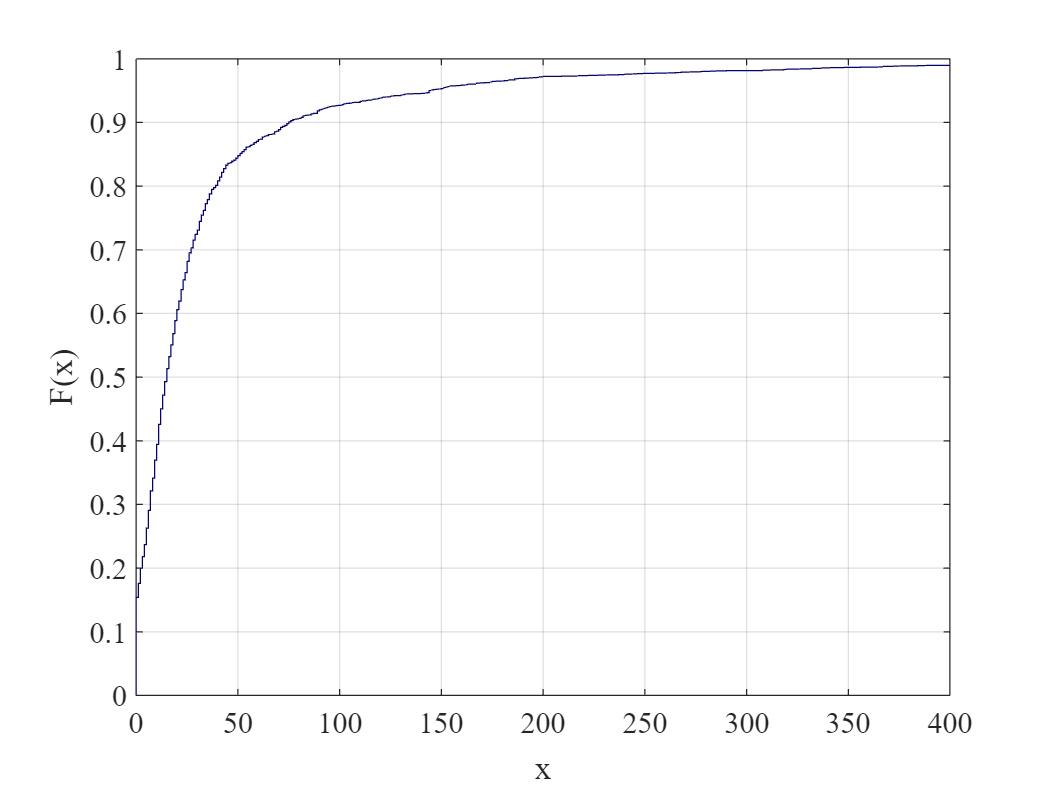

ecdf(responses.response_time - responses.cross_times)
xlim([0,400])

However, we want the distribution of bidding opportunity arrivals conditional on the time that a bidder is pushed OUTM. 

#### Part (i): estimate the CDF of bidding arrival times when $t=10$ and when $t=25$ and graph the CDFs

Recall that the formula for bidding arrival times is 


$$\widehat{G}_{t}(z)=\frac{\sum_{n=1}^{N}\sum_{j=0}^{J_{n}-1}K\left( \frac{%
\tau _{nj}-t}{h}\right) 1\{\rho _{n,j+1}-\tau _{nj}<z\}}{%
\sum_{n=1}^{N}\sum_{j=1}^{J_{n}}K\left( \frac{\tau _{nj}-t}{h}\right) }$$


where $\tau_{nj}$ is the time that the previous bid $j$ was pushed OUTM and $\rho_{n,j+1}$ is the time of the next bid $j+1$. While there are two summations in the formula, you can use a single sum over all the data points in the "responses" table. Use a Gaussian kernel with bandwidth parameter $h$ chosen using Silverman's rule of thumb.

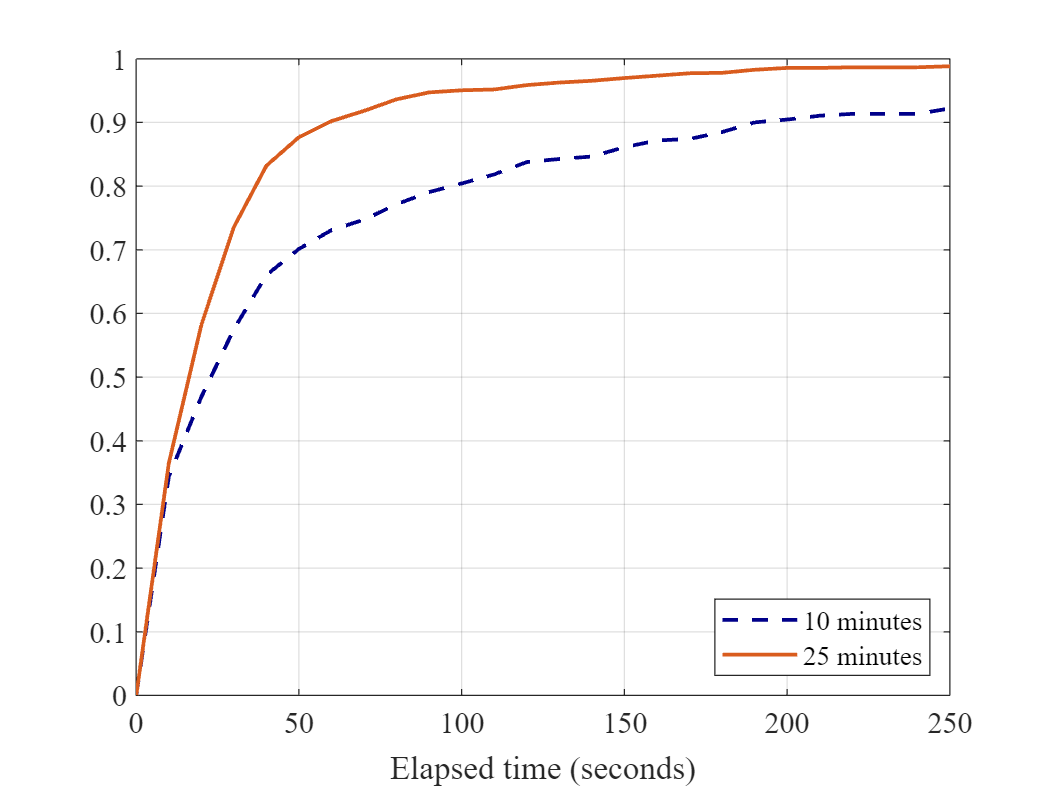


t=600; % ten minutes
x=(0:10:250)';
G_ten=[x, zeros(size(x))];
h=1.06*std(responses.cross_times)*(size(responses.cross_times,1))^(-1/5);

for j=1:size(G_ten,1)
    G_ten(j,2)=sum((responses.response_time-responses.cross_times<G_ten(j,1)).*normpdf((responses.cross_times-t)/h))/sum(normpdf((responses.cross_times-t)/h));
end



t=1500; % twentyfive minutes
x=(0:10:250)';
G_25=[x, zeros(size(x))];
h=1.06*std(responses.cross_times)*(size(responses.cross_times,1))^(-1/5);

for j=1:size(G_25,1)
    G_25(j,2)=sum((responses.response_time-responses.cross_times<G_25(j,1)).*normpdf((responses.cross_times-t)/h))/sum(normpdf((responses.cross_times-t)/h));
end

figure(1);
plot(x,G_ten(:,2),'--','LineWidth',1.5);
hold on; 
plot(x, G_25(:,2),'-','LineWidth',1.5);
hold off
legend('10 minutes','25 minutes','location','southeast');
xlabel('Elapsed time (seconds)');

### b. Estimating the distribution of valuations

load Data/pre_est_data.mat

#### Winning bids

The second data file contains the data relevant to estimating the distribution of valuations $F_V(\cdot)$. There are two arrays that contain bid data: "winning_bid_data" contains bids that won the auction, while "last" is a cell that contains information on bids that did not win the auction but were the last bid placed by a bidder in a given auction.

All bids have been assigned to a value on a discrete grid that goes from 0 to 1. These gridpoints are contained in the file "value_grid". *Note: for the purpose of this assignment, the grid is only 10 points.*

winning_bid_data(780:785)

ans =      4
     4
     6
     3
     3
     4


  Each entry in "winning_bid_data" references an index in "value_grid". If we want the bid values, instead of the indices, we plug them into the value_grid array:

value_grid(winning_bid_data(780:785))

ans =       0.33333      0.33333      0.55556      0.22222      0.22222      0.33333


#### Losing bids

The last bid placed by any losing bidder $i$ is contained in "last". Because the last bid is the highest bid placed by bidder $i$, it contains the most information about that bidder's valuation. Each entry in this cell is an array that documents each increase to the ONM rate *after *the last bid of bidder $i$ has been pushed OUTM. We need to document each ONM rate increase as there are two things that can occur during each increase and they have different implications for bidder $i$'s valuation. Suppose that the ONM rate increase from $r_{t}$ at time $t$ to $\tilde{r}_{\tau}$ at time $\tau$. Two things might have happened:   

- Bidder $i$ received an opportunity to bid in the interval $[t, \tau]$, but bidder $i$'s valuation was below $r_t$.

- Bidder $i$ never received an opportunity to bid (and her valuation may or may not have been below $r_t$).

Because we have already estimated the probability of receiving a bidding opportunity in Part 1, we can assign probabilities to each of these events and construct a likelihood function in terms of only bidder $i$'s valuation.

The cell "last" has 5 columns, but only three are useful for the purposes of this assignment. Ignore columns 1 and 2 in in estimation.

Column 3: the value grid index corresponding to the time t ONM rate.

Column 4: the value grid index corresponding to the time t-1 ONM rate.

Column 5: the CDF of the arrival rate distribution that gives the probability that a bid will have been received by the time of the ONM rate increase, starting from the time the last bid was pushed OUT. That is, this column is $G_{\tau}(t)$, where $\tau$ is the time the bidder's final bid was pushed OUT and $t$ is the time of the ONM rate increase.

#### Bid locations

Bid locations gives the indices of the sampled bid pairs used in the estimation. Columns 1 and 2 correspond to the first bid in the pair. Columns 3 and 4 correspond to the second bid in the pair. If column 1 is greater than zero, then that bid was a winning bid and column 1 gives the index of the winning bid in the winning_bid_data variable. Otherwise, if column 2 is greater than zero than the bid was not winning and the column gives the index of the losing bid data in the last variable.

The same holds for columns 3 and 4: column 3 corresponds to winning bids for the second bid in the pair, and column 4 corresponds to losing bids for the second bid in the pair.

Estimation proceeds by splitting the "bid_locations" variable into the cases described in the appendix and constructing the likelihood for each case. Note that the variable read into the likelihood function is a 100x1 vector; to work with the CDF in matrix form within the likelihood you should first reshape this vector into a matrix and take its transpose, e.g. "F=reshape(F_v,[10,10])';"

Finally, there are two additional files: starting_guess, which contains an initial point for the optimizer, and constraint_conditions. The optimization imposes constraints on the solution, specifically that we need the solution to be a valid joint CDF (weakly increasing, values between zero and one, etc.). The constraint conditions file gives the variables needed by the optimizer to impose these conditions in estimation when using the "fmincon" function.

***IMPORTANT: ***make sure you have the most recent version of Matlab installed, as the optimizer uses the "EnableFeasibilityMode" option which may not be available on previous releases. If you can't use this mode you can delete this section of code in the optimizer call below, but be warned that you may converge to an infeasible point!

When sampling pairs of bids from the set of all bids, we categorize each pair into the four possible outcomes, explained in appendix C.2: both bids are winning bids, the first wins while the second loses, the first loses while the second wins, or both bids lose. The likelihood function, "joint_likelihood" contained at the end of this document, separately calculates these four components. 

load Data/constraint_conditions.mat % loads the constraints used in the optimization routine
load Data/starting_guess.mat % loads the starting guess used for the optimizer (a randomly sampled independent uniform joint distribution)

N_value=10;
v_grid=value_grid';

likelihood_fun=@(F)joint_likelihood(F,winning_bid_data,last,bid_locations);

options=optimoptions('fmincon','Display','iter','TolCon',1e-6,'TolX',1e-6,'MaxFunEvals',60000,'ConstraintTolerance',1e-6,'EnableFeasibilityMode',true,'SubproblemAlgorithm','cg');
F_v=fmincon(likelihood_fun,F0,constraint_matrix,b,Aeq,beq,lb,[],[],options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     101    6.727903e+03    0.000e+00    3.021e+03
Objective function returned complex; trying a new point...
    1     203    6.061853e+03    1.600e-03    8.873e+02    5.724e-01
Objective function returned complex; trying a new point...
    2     306    5.891587e+03    3.415e-03    5.311e+02    2.213e-01
Objective function returned complex; trying a new point...
    3     409    5.776431e+03    6.464e-03    4.614e+02    1.817e-01
Objective function returned complex; trying a new point...
    4     513    5.732364e+03    7.562e-03    4.343e+02    7.962e-02
Objective function returned complex; trying a new point...
    5     617    5.698581e+03    8.265e-03    3.989e+02    6.598e-02
Objective function returned complex; trying a new point...
    6     720    5.647085e+03    9.056e-03    3.286e+02    1.107e-01
Objective function returned complex; t

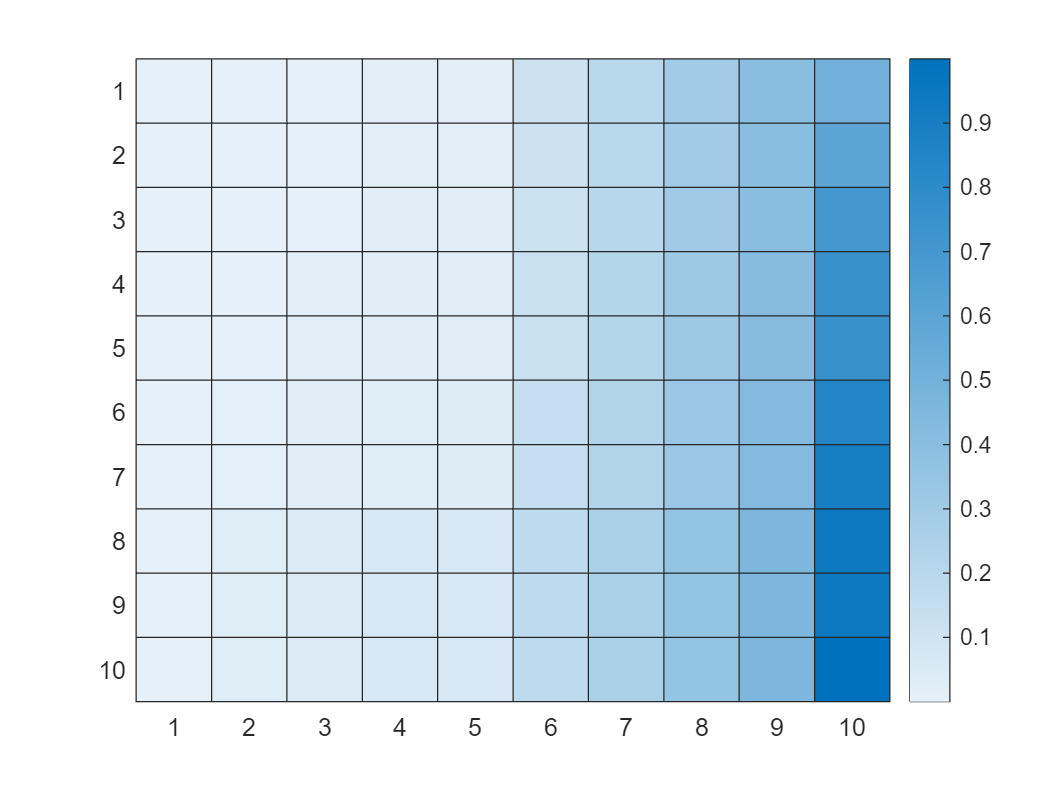


heatmap(reshape(F_v,[10,10]))

### c. Deconvolution

The last component of the estimation is using the deconvolution techniques of Kotlarski (1966) and applied to economics by Li and Vuong (1998), and Krasnokutskaya (2011). The basic idea of deconvolution is to use the joint distribution of pairs of observations to recover the underlying random processes that govern the joint distribution. More concretely, suppose we have a two random variables $Z_1,Z_2$, with


$$\begin{array}{l}
Z_1 =Y+X_1 ,\;\;\;\\
Z_2 =Y+X_2 \ldotp 
\end{array}$$


Assume further that $X_1$, $X_2$, and $Y$ are mutually independent. Clearly $Z_1$ and $Z_2$ are not independent variables, as they are correlated by the realization of $Y$. Kotlarski (1966) showed that the distributions of $X_1$, $X_2$, and $Y$ are uniquely determined by the joint distribution of $Z_1,Z_2$ up to the location of $Y$ (that is, we have to fix the mean of $Y$in estimation). *Note: we can also apply these techniques in the exact same way if there is a multiplicative structure *$Z_i = YX_i$ *by taking logs.*

Specifically, with the characteristic function of $(\ln(V_1),\ln(V_2))$, $\phi_{V_1,V_2}(t_1,t_2)$, we can recover the characteristic functions of $\ln(Y)$ and $\ln(X)
$, $\phi_{\ln(X)}(t)$ and $\phi_{\ln(Y)}
(t)$ as


$$
\hat{\phi}_{\ln Y}(t) = \exp \left( \int_{0}^{t}\frac{\partial }{\partial u}
\left[ \frac{\hat{\phi}_{\ln V_{1},\ln V_{2}}(u,v)}{\hat{\phi}_{\ln V_{1},\ln V_{2}}(u,0)%
\hat{\phi}_{\ln V_{1},\ln V_{2}}(0,v)}\right] _{u=0}dv\right) 
$$



$$\hat{\phi}_{\ln X}(t) =\frac{\hat{\phi}_{\ln V_{1},\ln V_{2}}(t,0)}{\hat{\phi}_{\ln Y}(t)}
$$


We can recover the pdf of these random variables from the characteristic functions using the inverse Fourier transform:


$$\hat{p}_{\ln Y}(y) =\frac{1}{2\pi }\int_{-T}^{T}e^{ity}\hat{\phi}_{\ln Y}(t)dt$$


These techniques are useful for auctions as they allow for the introduction of *unobserved auction heterogeneity*: we typically assume that bidders' valuations are independent within an auction, possibly after controlling for a set of observable covariates. However, if there are relevant covariates that are *unobserved* to the econometrician, this assumption will be violated: valuations will not be independent due to the correlation induced by this unobserved factor. Deconvolution approaches allow for the econometrician to control for the presence of these factors, and was pioneered in this context by Krasnokutskaya (2011).

Deconvolution approaches are also useful in other contexts, especially the measurement error literature. Suppose we have two realizations of wages, $W_1$ and $W_2$, but both come from data sets of poor quality and there are concerns about measurement error in wages influencing regression results. If we fix average wages (that is, we set $E[Y] = \overline{w}$, where $\overline{w}$ comes from more accurate aggregate statistics), then we can estimate and control for the measurement error components $X_1$ and $X_2$ using deconvolution. Li and Vuong (1998) first applied these techniques in econometrics, and Schennach (2004 Econometrica) provides a more comprehensive treatment.

For our purposes, we are going to use a toy data set to demonstrate how deconvolution works. First we load the last data set, which contains realizations from a joint distribution of (continuous) random variables $z_1,z_2$. 

load Data/deconv_data

$z_1,z_2$ come from a distribution generated by $(Z_1, Z_2) = (Y X_1, YX_2)$ for $Y, X$ mutually independent and $X_1, X_2 \sim F(\cdot)$, with $z_i \equiv \log(Z_i)$. (Note: the X's are i.i.d and follow the same distribution).

Last step: evaluate the deconvolution method using the code below and graph the results. Finally, we perform the change of variables to "un-logarithm" the resulting random variables, and plot the results as a cdf instead of a pdf.

[y,x,Y_grid,X_grid]=deconvolution(v) % This takes inputs v, an Nx2 vector, and outputs y, which is the pdf of Y, and x, which is the pdf of X.
% Each pdf is evaluated at a set of grid points.
figure(1);plot(Y_grid,y);
figure(2); plot(X_grid,x);

## Appendix: Functions

Joint likelihood:

function [lik]=joint_likelihood(F_v,winning_bids,last,bid_locations)

% F is read in as a 100x1 vector: reshape to 10x10 matrix
F=reshape(F_v,[10,10])';

% Break into cases

% Win-win
win_win_locs=bid_locations(bid_locations(:,1)>0 & bid_locations(:,3)>0,[1,3]);
L1=diag(1-F(winning_bids(win_win_locs(:,1)),winning_bids(win_win_locs(:,2))));

% Win-lose

win_lose_locs=bid_locations(bid_locations(:,1)>0 & bid_locations(:,4)>0,[1,4]);
L2_2=zeros(size(win_lose_locs,1),1);
for j=1:size(win_lose_locs,1)
    L2_2(j)=sum((F(end,last{win_lose_locs(j,2),1}(:,3))-F(winning_bids(win_lose_locs(j,1)),last{win_lose_locs(j,2),1}(:,3))).*(1-last{win_lose_locs(j,2),1}(:,5))')... 
        +(1-(F(winning_bids(win_lose_locs(j,1)),end)+(F(end,last{win_lose_locs(j,2),1}(1,4))-F(winning_bids(win_lose_locs(j,1)),last{win_lose_locs(j,2),1}(1,4)))))*(1-last{win_lose_locs(j,2),1}(end,5)); % Defines "rectangle" of valuations grid
end

L2=L2_2;

% Lose-win: same as above with roles reversed
lose_win_locs=bid_locations(bid_locations(:,2)>0 & bid_locations(:,3)>0,[2,3]);
lose_win_locs=[lose_win_locs(:,2),lose_win_locs(:,1)];

L3_2=zeros(size(lose_win_locs,1),1);
for j=1:size(lose_win_locs,1)
    L3_2(j)=sum((F(end,last{lose_win_locs(j,2),1}(:,3))-F(winning_bids(lose_win_locs(j,1)),last{lose_win_locs(j,2),1}(:,3))).*(1-last{lose_win_locs(j,2),1}(:,5))')... 
        +(1-(F(winning_bids(lose_win_locs(j,1)),end)+(F(end,last{lose_win_locs(j,2),1}(1,4))-F(winning_bids(lose_win_locs(j,1)),last{lose_win_locs(j,2),1}(1,4)))))*(1-last{lose_win_locs(j,2),1}(end,5)); % Define rectangle of valuations grid
end

L3=L3_2;

% Lose-Lose
lose_lose_locs=bid_locations(bid_locations(:,2)>0 & bid_locations(:,4)>0,[2,4]);
L4=zeros(size(lose_lose_locs,1),1);
for j=1:size(lose_lose_locs,1)
    temp_F=(F(last{lose_lose_locs(j,1),1}(:,3),last{lose_lose_locs(j,2),1}(:,3))-F(last{lose_lose_locs(j,1),1}(:,4),last{lose_lose_locs(j,2),1}(:,3)))...
        -(F(last{lose_lose_locs(j,1),1}(:,3),last{lose_lose_locs(j,2),1}(:,4))-F(last{lose_lose_locs(j,1),1}(:,4),last{lose_lose_locs(j,2),1}(:,4)));
    
    L4(j)=(1-(F(last{lose_lose_locs(j,1),1}(end,4),end)+(F(end,last{lose_lose_locs(j,2),1}(1,4))-F(last{lose_lose_locs(j,1),1}(end,4),last{lose_lose_locs(j,2),1}(1,4)))))*(1-last{lose_lose_locs(j,2),1}(end,5))*(1-last{lose_lose_locs(j,1),1}(end,5))...
        +(1-last{lose_lose_locs(j,2),1}(end,5))*sum((F(last{lose_lose_locs(j,1)}(:,3),end)-F(last{lose_lose_locs(j,1)}(:,4),end))-(F(last{lose_lose_locs(j,1)}(:,4),last{lose_lose_locs(j,2)}(end,3))-F(last{lose_lose_locs(j,1)}(:,4),last{lose_lose_locs(j,2)}(end,4))).*(1-last{lose_lose_locs(j,1)}(:,5)))...
        +(1-last{lose_lose_locs(j,1),1}(end,5))*sum((F(end,last{lose_lose_locs(j,2)}(:,3))-F(end,last{lose_lose_locs(j,2)}(:,4)))-(F(last{lose_lose_locs(j,1)}(end,3),last{lose_lose_locs(j,2)}(:,4))-F(last{lose_lose_locs(j,1)}(end,4),last{lose_lose_locs(j,2)}(:,4))).*(1-last{lose_lose_locs(j,2)}(:,5))')... 
        +(1-last{lose_lose_locs(j,1),1}(:,5))'*temp_F*(1-last{lose_lose_locs(j,2),1}(:,5));
end
L4(L4<=0)=[];


lik=(-1)*(sum(log(L1))+sum(log(L2))+sum(log(L3))+sum(log(L4)));
end

Deconvolution:

function [y,z,Y_grid,Z_grid]=deconvolution(Z)

Y_grid=linspace(-4,0,20);
Z_grid=linspace(-1.5,2.5,20);
Y_pdf=zeros(size(Y_grid,2),1);
Z_pdf=zeros(size(Z_grid,2),1);

T=3;
T2=10;


fun1=@(U) arrayfun(@(u) exp(integral(@(t1) psi1_psi(t1,Z),0,u)),U);

fun2=@(U) arrayfun(@(u) characteristic_function(u,0,Z)./(exp(integral(@(t1) psi1_psi(t1,Z),0,u))),U);
% Dampening factor:(1-(abs(t)/T2)).*
for j=1:size(Y_grid,2)
    Y_pdf(j)=(1/(2*pi))*integral(@(t) (1-(abs(t)/T)).*exp(-1i.*t.*Y_grid(j)).*fun1(t),-T,T);
    Z_pdf(j)=(1/(2*pi))*integral(@(t) (1-(abs(t)/T2)).*exp(-1i.*t.*Z_grid(j)).*fun2(t),-T2,T2);
end
Y_pdf=real(Y_pdf);
Y_mean=trapz(Y_grid,Y_grid'.*Y_pdf);


y=Y_pdf;
z=real(Z_pdf);

end

function char=characteristic_function(t1,t2,Z)
char=mean(exp(1i.*t1.*Z(:,1) + 1i.*t2.*Z(:,2)));
end

function ratio=psi1_psi(t1,Z)
ratio=((characteristic_function(1e-2,t1,Z)-characteristic_function(-1e-2,t1,Z))./2e-2)./characteristic_function(0,t1,Z);
end
